Modern Control Project Phase 2

Fatemeh Naeinian     SID=810198479

part 1

syms x1 x2 x3 u;

R = 50; 
L = 0.2; 
g = 9.8; 
M = 0.4+0.079; 
c = 0.3; 
fv = 0.04; 
ystar = 0.06;
x1star = 0.06;
x2star = 0;
x3star = 0.791134207;
ustar = -39.55671034;

A = [0, 1, 0;c/M*x3star^2/(0.1-x1star)^2, -fv/M, -c/M*x3star*2/(0.1-x1star); 0, 0, -R/L]

A =          0    1.0000         0
  245.0000   -0.0835  -24.7746
         0         0 -250.0000


B = [0 0, 1/L]';
C = [1, 0, 0];
D = 0;

x = [x1-x1star, x2-x2star, x3-x3star]'

$$x = \left(\begin{array}{c} \bar{x_{1}}-\frac{3}{50}\\ \bar{x_{2}}\\ \bar{x_{3}}-\frac{3562951719845253}{4503599627370496} \end{array}\right)$$

xdot = A*x + B*u;
y = C*x + D*u - ystar

$$y = \bar{x_{1}}-\frac{3}{25}$$

Controlable = [B, A*B, A*A*B];

Observable = [C; C*A; C*A*A];
s=tf('s');
gs=C*((s.*eye(3)-A)^-1)*B+D

gs =
 
                 -123.9
  ------------------------------------
  s^3 + 250.1 s^2 - 224.1 s - 6.125e04
 
Continuous-time transfer function.



part 1

p = [-5 -7 -10];
K = place(A,B,p)

K =   -46.1727   -3.2143  -45.6167


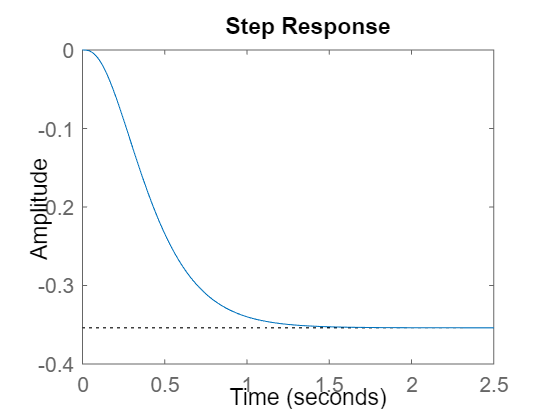

A2 = A - B * K;
sys2 = ss(A2,B,C,D);
step(sys2)

figure;

p1 = [-100 -150 -200];
K1 = place(A,B,p1)

K1 = 1.0e+04 *

   -2.5108   -0.0526    0.0040


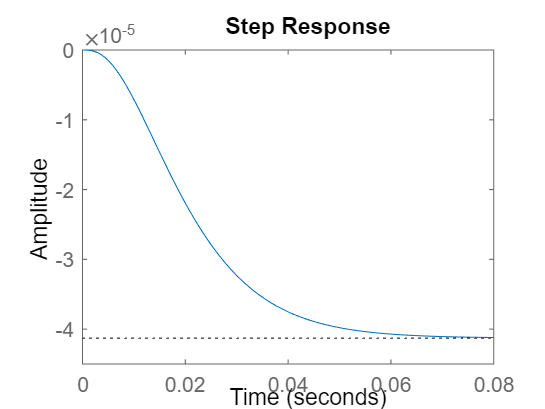

A3 = A - B * K1;
sys3 = ss(A3,B,C,D);
step(sys3)

part 3

eig(A)

ans =    15.6108
  -15.6943
 -250.0000


A_bar = [0, 1, 0, 0;
    c/M*x3star^2/(0.1-x1star)^2, -fv/M, -c/M*x3star*2/(0.1-x1star), 0;
    0, 0, -R/L, 0;
    1, 0, 0, 0];

B_bar = [0 0, 1/L 0]';

Co = ctrb(A_bar, B_bar);
rank_Co = rank (Co)

rank_Co = 4


pp = [-10 , -16 , -22 , -27];
K2 = place(A_bar,B_bar,pp)

K2 =  -336.1395  -18.2990  -35.0167 -767.2387


k1=K2(1);k2=K2(2);k3=K2(3);k4=K2(4);
k123=[k1,k2,k3]

k123 =  -336.1395  -18.2990  -35.0167


part 4

Ob = obsv(A, C);
rank_ob = rank (Ob)

rank_ob = 3

%%
ppp=[-5 , -7 , -10 ];
K4 =place(A' , C' , ppp);
L1 = K4'

L1 = 1.0e+05 *

   -0.0023
    0.5742
    5.7674


Al = A - L1*C

Al = 1.0e+05 *

    0.0023    0.0000         0
   -0.5717   -0.0000   -0.0002
   -5.7674         0   -0.0025


part 5 

 F = [1 2 ; -3 -4];
 l=[6 ; 9];
 rank_c = rank(ctrb(F , l))

rank_c = 2

 A1 = -F;
 T = lyap(A1 , A , -l*C)

T =     0.1032    0.0231   -0.0022
   -0.2224    0.0391   -0.0040


 P=[C;T];
 P_inv = inv(P)

P_inv = 1.0e+04 *

    0.0001         0         0
   -0.0247    0.1077   -0.0611
   -0.2493    1.0625   -0.6275


 rank_p = rank(P)

rank_p = 3

 TB = T*B

TB =    -0.0112
   -0.0198
